# Fault Detection

Pieter Leon van den Berg

22684166

20 October 2022

Final Year Project (C) 478

Supervisor: Dr Cripwell

### Setup

clear;
clc;

## Settings

### Data export

SAVE_IMAGES = true;                             % Save the generated graphs
SAVE_DATA   = true;                             % Save the generated data

### PCA

NUMBER_OF_PRINCIPLE_COMPONENTS_TO_USE = 7;      % Number of principle components to use for the reduced subspace 

### Control charts

T2_ALPHA = 30;                                  % UCL for the Hotelling's T2 statistic
Q_ALPHA  = 3;                                   % UCL for the Q-statistic

### Process state plotting

PROCESS_STATE_PLOTTING_REDUCED = true;          % Only plot the single-fault states when set to true

## PCA

### Read the training data to use for PCA

TRAINING_DATA = readtable('fault_detection\data\normal_training.csv')

TRAINING_DATA = 24001×19 table
    Time    c_LO_measured    c_RE_measured    f_PLSP_measured    f_PLSS_measured    f_LO_measured    f_LE_measured    c_PLS_measured    c_LE_measured    c_RaffP_measured    c_RaffS_measured    c_BO_measured    v_LO_control    v_LO_valve    v_LE_control    v_LE_valve    v_LO_state    v_LE_state    process_state
    ____    _____________    _____________    _______________    _______________    _____________    _____________    ______________    _____________    ________________

### Read the timeseries

% Read the time of the training data
training_time = TRAINING_DATA.Time;

% Read the timeseries variables of the training data
training_c_LO    = TRAINING_DATA.c_LO_measured;
training_c_RE    = TRAINING_DATA.c_RE_measured;
training_f_PLSP  = TRAINING_DATA.f_PLSP_measured;
training_f_PLSS  = TRAINING_DATA.f_PLSS_measured;
training_f_LO    = TRAINING_DATA.f_LO_measured;
training_f_LE    = TRAINING_DATA.f_LE_measured;
training_c_PLS   = TRAINING_DATA.c_PLS_measured;
training_c_LE    = TRAINING_DATA.c_LE_measured;
training_c_RaffP = TRAINING_DATA.c_RaffP_measured;
training_c_RaffS = TRAINING_DATA.c_RaffS_measured;
training_c_BO    = TRAINING_DATA.c_BO_measured;

% Read the process state of the training data
training_process_state = TRAINING_DATA.process_state;

### Normalize the training data

% Determining the means of the training data
c_LO_mu    = mean(training_c_LO);
c_RE_mu    = mean(training_c_RE);
f_PLSP_mu  = mean(training_f_PLSP);
f_PLSS_mu  = mean(training_f_PLSS);
f_LO_mu    = mean(training_f_LO);
f_LE_mu    = mean(training_f_LE);
c_PLS_mu   = mean(training_c_PLS);
c_LE_mu    = mean(training_c_LE);
c_RaffP_mu = mean(training_c_RaffP);
c_RaffS_mu = mean(training_c_RaffS);
c_BO_mu    = mean(training_c_BO);

% Determining the standard deviations of the training data
c_LO_sigma    = std(training_c_LO);
c_RE_sigma    = std(training_c_RE);
f_PLSP_sigma  = std(training_f_PLSP);
f_PLSS_sigma  = std(training_f_PLSS);
f_LO_sigma    = std(training_f_LO);
f_LE_sigma    = std(training_f_LE);
c_PLS_sigma   = std(training_c_PLS);
c_LE_sigma    = std(training_c_LE);
c_RaffP_sigma = std(training_c_RaffP);
c_RaffS_sigma = std(training_c_RaffS);
c_BO_sigma    = std(training_c_BO);

% Normalize the training data
training_c_LO_normalized    = (training_c_LO    - c_LO_mu   ) ./ c_LO_sigma;
training_c_RE_normalized    = (training_c_RE    - c_RE_mu   ) ./ c_RE_sigma;
training_f_PLSP_normalized  = (training_f_PLSP  - f_PLSP_mu ) ./ f_PLSP_sigma;
training_f_PLSS_normalized  = (training_f_PLSS  - f_PLSS_mu ) ./ f_PLSS_sigma;
training_f_LO_normalized    = (training_f_LO    - f_LO_mu   ) ./ f_LO_sigma;
training_f_LE_normalized    = (training_f_LE    - f_LE_mu   ) ./ f_LE_sigma;
training_c_PLS_normalized   = (training_c_PLS   - c_PLS_mu  ) ./ c_PLS_sigma;
training_c_LE_normalized    = (training_c_LE    - c_LE_mu   ) ./ c_LE_sigma;
training_c_RaffP_normalized = (training_c_RaffP - c_RaffP_mu) ./ c_RaffP_sigma;
training_c_RaffS_normalized = (training_c_RaffS - c_RaffS_mu) ./ c_RaffS_sigma;
training_c_BO_normalized    = (training_c_BO    - c_BO_mu   ) ./ c_BO_sigma;

### Perform PCA on the training data

% Create the normalized training data matrix
training_X = [training_c_LO_normalized, training_c_RE_normalized, training_f_PLSP_normalized, training_f_PLSS_normalized, ...
                                  training_f_LO_normalized, training_f_LE_normalized, training_c_PLS_normalized, training_c_LE_normalized,    ...
                                  training_c_RaffP_normalized, training_c_RaffS_normalized, training_c_BO_normalized];

% Perform the PCA on the normalized training data
[PCA_coeff, training_Z, PCA_latent, PCA_tsquared, PCA_explained, PCA_mu] = pca(training_X);

### Setup plotting

% Line styles
line_width = 0.8;

% Colours
blue  = '#06ACE9';
white = '#FFFFFF';

### Scree plot

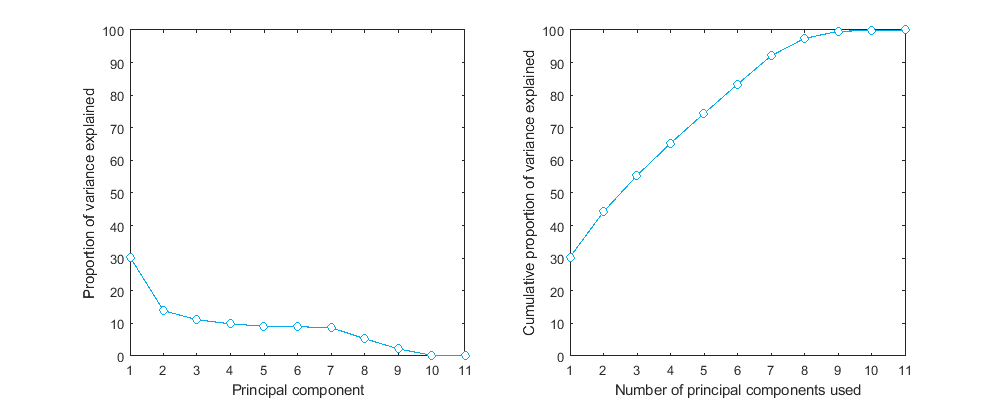

% Create the scree plot figure
figure()

% Plot the proportion of variance explained
subplot(1,2,1)
plot(PCA_explained, '-o', 'LineWidth',line_width, 'Color', blue, 'MarkerFaceColor', white, 'MarkerEdgeColor', blue, 'MarkerSize', 6)
ylabel("Proportion of variance explained")
xlabel("Principal component")
ylim([0 100])
xlim([1 11])
xticks([1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11])

% Plot the cumulative proportion of variance explained
subplot(1,2,2)
plot(cumsum(PCA_explained), '-o', 'LineWidth',line_width, 'Color', blue, 'MarkerFaceColor', white, 'MarkerEdgeColor', blue, 'MarkerSize', 6)
ylabel("Cumulative proportion of variance explained")
xlabel("Number of principal components used")
ylim([0 100])
xlim([1 11])
xticks([1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11])

% Set the plot size
fig_scree_plot = gcf;
fig_scree_plot.Position(3:4) = [1000, 400];

% Save the current figure
if (SAVE_IMAGES)
    print('fault_detection/output/PCA/scree_plot', '-dpng', '-r600')
end

### PCA loadings

% Variable labels
measured_variable_labels = categorical({'c_{LO}', 'c_{RE}', 'f_{PLSP}', 'f_{PLSS}', 'f_{LO}', 'f_{LE}', 'c_{PLS}', 'c_{LE}', 'c_{RaffP}', 'c_{RaffS}', 'c_{BO}'});
measured_variable_labels = reordercats(measured_variable_labels, {'c_{LO}', 'c_{RE}', 'f_{PLSP}', 'f_{PLSS}', 'f_{LO}', 'f_{LE}', 'c_{PLS}', 'c_{LE}', 'c_{RaffP}', 'c_{RaffS}', 'c_{BO}'});

### Principal component 1

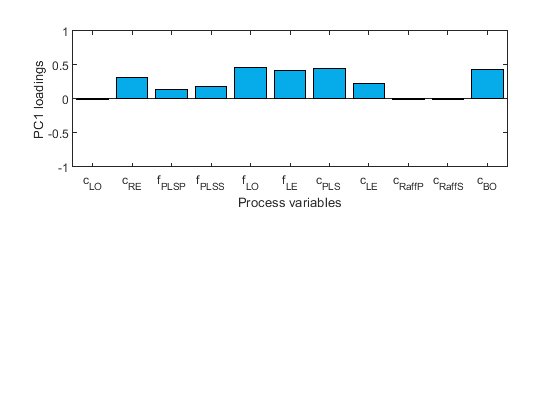

% Create the figure for the 1st principal component
figure()

% Plot the proportion of variance explained
subplot(2,1,1)
bar(measured_variable_labels, PCA_coeff(:,1), 'FaceColor', blue)
ylabel('PC1 loadings')
xlabel('Process variables')
ylim([-1 1])

% Save the current figure
if (SAVE_IMAGES)
    print('fault_detection/output/PCA/PC1_loadings', '-dpng', '-r600')
end

### Principal component 2

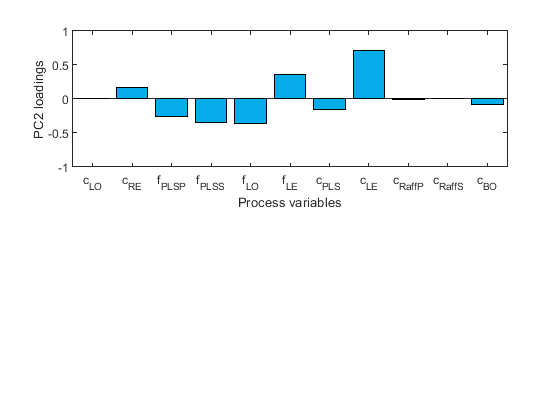

% Create the figure for the 2nd principal component
figure()

% Plot the proportion of variance explained
subplot(2,1,1)
bar(measured_variable_labels, PCA_coeff(:,2), 'FaceColor', blue)
ylabel('PC2 loadings')
xlabel('Process variables')
ylim([-1 1])

% Save the current figure
if (SAVE_IMAGES)
    print('fault_detection/output/PCA/PC2_loadings', '-dpng', '-r600')
end

### Principal component 3

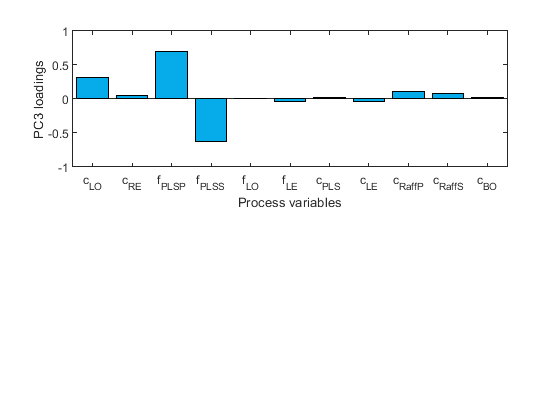

% Create the figure for the 3rd principal component
figure()

% Plot the proportion of variance explained
subplot(2,1,1)
bar(measured_variable_labels, PCA_coeff(:,3), 'FaceColor', blue)
ylabel('PC3 loadings')
xlabel('Process variables')
ylim([-1 1])

% Save the current figure
if (SAVE_IMAGES)
    print('fault_detection/output/PCA/PC3_loadings', '-dpng', '-r600')
end

### Principal component 4

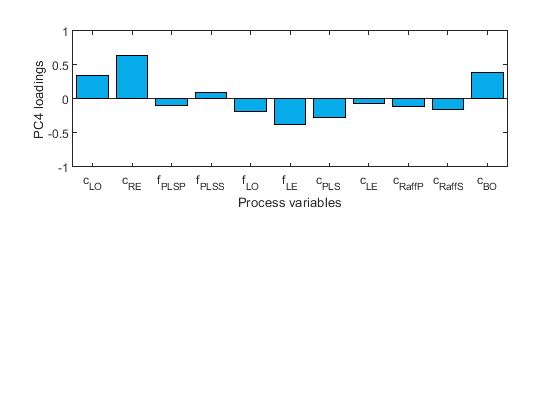

% Create the figure for the 4th principal component
figure()

% Plot the proportion of variance explained
subplot(2,1,1)
bar(measured_variable_labels, PCA_coeff(:,4), 'FaceColor', blue)
ylabel('PC4 loadings')
xlabel('Process variables')
ylim([-1 1])

% Save the current figure
if (SAVE_IMAGES)
    print('fault_detection/output/PCA/PC4_loadings', '-dpng', '-r600')
end

### Principal component 5

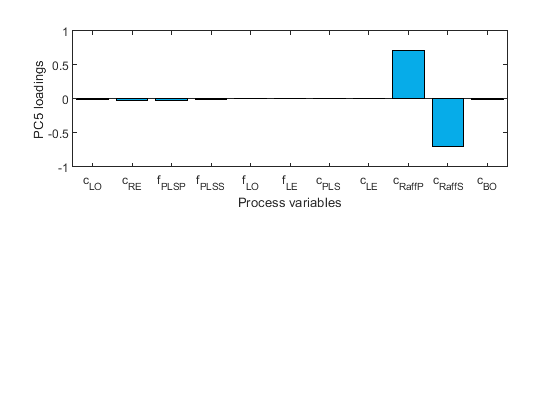

% Create the figure for the 5th principal component
figure()

% Plot the proportion of variance explained
subplot(2,1,1)
bar(measured_variable_labels, PCA_coeff(:,5), 'FaceColor', blue)
ylabel('PC5 loadings')
xlabel('Process variables')
ylim([-1 1])

% Save the current figure
if (SAVE_IMAGES)
    print('fault_detection/output/PCA/PC5_loadings', '-dpng', '-r600')
end

### Principal component 6

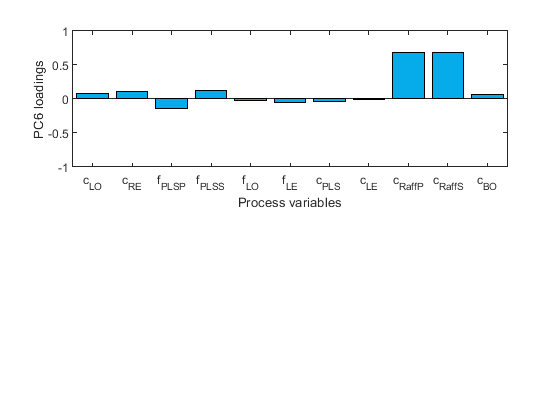

% Create the figure for the 6th principal component
figure()

% Plot the proportion of variance explained
subplot(2,1,1)
bar(measured_variable_labels, PCA_coeff(:,6), 'FaceColor', blue)
ylabel('PC6 loadings')
xlabel('Process variables')
ylim([-1 1])

% Save the current figure
if (SAVE_IMAGES)
    print('fault_detection/output/PCA/PC6_loadings', '-dpng', '-r600')
end

### Principal component 7

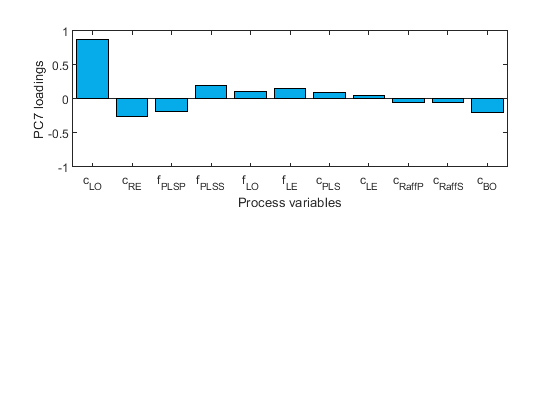

% Create the figure for the 7th principal component
figure()

% Plot the proportion of variance explained
subplot(2,1,1)
bar(measured_variable_labels, PCA_coeff(:,7), 'FaceColor', blue)
ylabel('PC7 loadings')
xlabel('Process variables')
ylim([-1 1])

% Save the current figure
if (SAVE_IMAGES)
    print('fault_detection/output/PCA/PC7_loadings', '-dpng', '-r600')
end

### Principal component 8

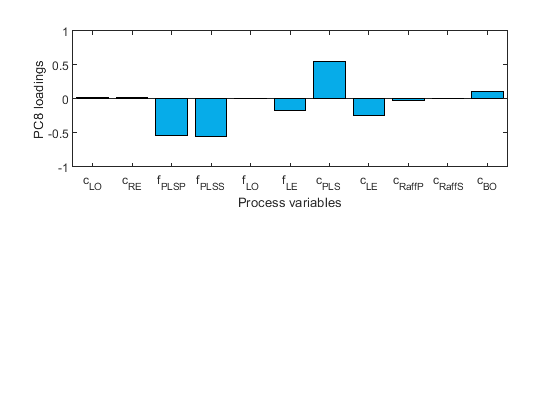

% Create the figure for the 8th principal component
figure()

% Plot the proportion of variance explained
subplot(2,1,1)
bar(measured_variable_labels, PCA_coeff(:,8), 'FaceColor', blue)
ylabel('PC8 loadings')
xlabel('Process variables')
ylim([-1 1])

% Save the current figure
if (SAVE_IMAGES)
    print('fault_detection/output/PCA/PC8_loadings', '-dpng', '-r600')
end

### Principal component 9

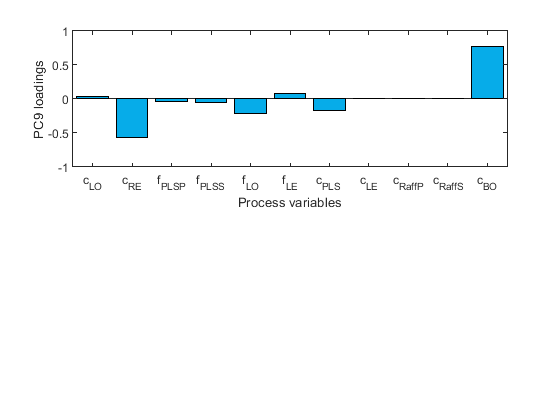

% Create the figure for the 9th principal component
figure()

% Plot the proportion of variance explained
subplot(2,1,1)
bar(measured_variable_labels, PCA_coeff(:,9), 'FaceColor', blue)
ylabel('PC9 loadings')
xlabel('Process variables')
ylim([-1 1])

% Save the current figure
if (SAVE_IMAGES)
    print('fault_detection/output/PCA/PC9_loadings', '-dpng', '-r600')
end

### Principal component 10

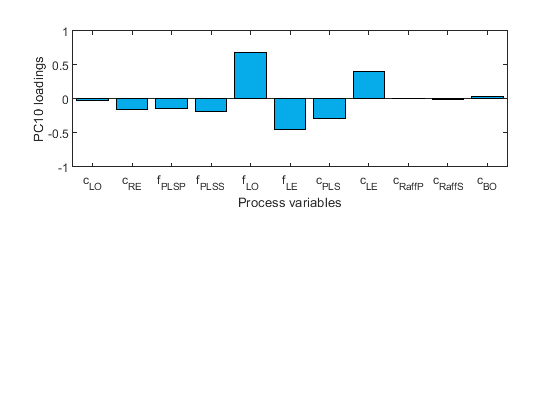

% Create the figure for the 10th principal component
figure()

% Plot the proportion of variance explained
subplot(2,1,1)
bar(measured_variable_labels, PCA_coeff(:,10), 'FaceColor', blue)
ylabel('PC10 loadings')
xlabel('Process variables')
ylim([-1 1])

% Save the current figure
if (SAVE_IMAGES)
    print('fault_detection/output/PCA/PC10_loadings', '-dpng', '-r600')
end

### Principal component 11

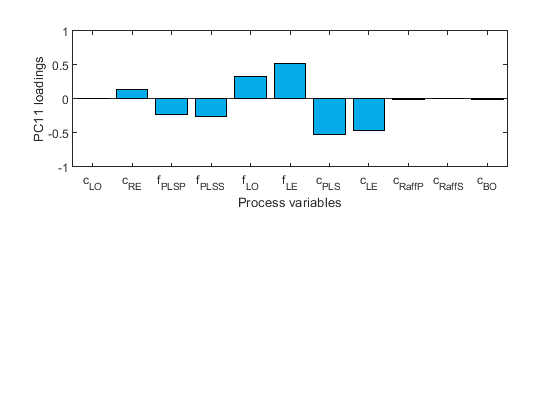

% Create the figure for the 11th principal component
figure()

% Plot the proportion of variance explained
subplot(2,1,1)
bar(measured_variable_labels, PCA_coeff(:,11), 'FaceColor', blue)
ylabel('PC11 loadings')
xlabel('Process variables')
ylim([-1 1])

% Save the current figure
if (SAVE_IMAGES)
    print('fault_detection/output/PCA/PC11_loadings', '-dpng', '-r600')
end

### PCA matrices

% Singular value matrix
SIGMA = diag(PCA_latent);
SIGMA_inv = inv(SIGMA);

% Reduced subspace singular value matrix
SIGMA_reduced = diag(PCA_latent(1:NUMBER_OF_PRINCIPLE_COMPONENTS_TO_USE));
SIGMA_reduced_inv = inv(SIGMA_reduced);

% Principal component loadings
PCA_loadings = PCA_coeff;
PCA_loadings_reduced = PCA_loadings(:, 1:NUMBER_OF_PRINCIPLE_COMPONENTS_TO_USE);

% Principal component scores
training_Z_reduced = training_Z(:, 1:NUMBER_OF_PRINCIPLE_COMPONENTS_TO_USE);

### Reconstructed PCA data matrix

% Reconstructed PCA data matrix
training_X_subspace = training_Z_reduced*PCA_loadings_reduced';
training_X_residual = training_X - training_X_subspace;

### Training Hotelling's T2 statistic

% Preallocate the size of the training Hotelling's T2 statistic array
training_T2 = zeros(length(training_time),1);

% Calculate the Hotelling's T2 statistics of the training data
for i = 1:length(training_time)    
    training_T2(i) = training_Z_reduced(i,:)*SIGMA_reduced_inv*training_Z_reduced(i,:)';
end

### Training Q statistic

% Preallocate the size of the training Q statistic array
training_Q = zeros(length(training_time),1);

% Calculate the Q statistics of the training data
for i = 1:length(training_time)    
    training_Q(i) = norm(training_X_residual(i,:));    
end

### Training control chart

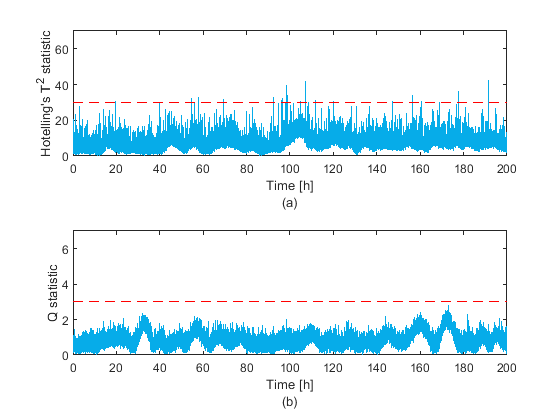

% Create the figure for the training control charts
figure()

% Plot the training Hotelling's T2 statistic
subplot(2,1,1)
plot(training_time/(60*60), training_T2, '-', 'Color', blue, 'LineWidth',line_width)
hold on
plot([0 training_time(end)/(60*60)], [T2_ALPHA T2_ALPHA], '--r', 'LineWidth',line_width)
hold off
ylabel("Hotelling's T^{2} statistic")
xlabel(["Time [h]", "(a)"])
ylim([0, 70])

% Plot the training Q statistic
subplot(2,1,2)
plot(training_time/(60*60), training_Q, '-', 'Color', blue, 'LineWidth',line_width)
hold on
plot([0 training_time(end)/(60*60)], [Q_ALPHA Q_ALPHA], '--r', 'LineWidth',line_width)
hold off
ylabel("Q statistic")
xlabel(["Time [h]", "(b)"])
ylim([0, 7])

% Save the current figure
if (SAVE_IMAGES)
    print('fault_detection/output/fault_detection/training_control_chart', '-dpng', '-r600')
end

### Training process state

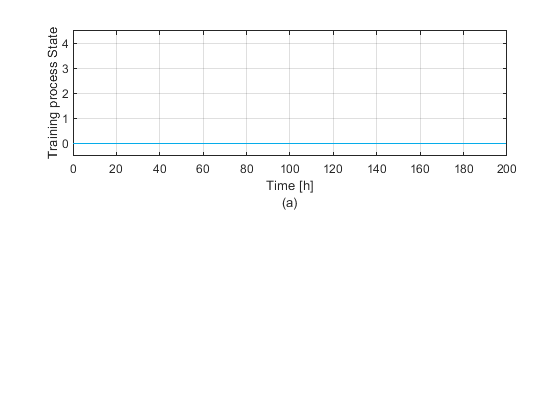

% Create the figure for the process state
figure()

% Plot the training process state
subplot(2,1,1)
plot(training_time/(60*60), training_process_state, 'Color', blue,'LineWidth', line_width)
ylabel("Training process State")
xlabel(["Time [h]", "(a)"])
grid on
% Only plot the single-fault process states if
% PROCESS_STATE_PLOTTING_REDUCED == true
if (PROCESS_STATE_PLOTTING_REDUCED == true)
    ylim([-0.5 4.5])
    yticks([0, 1, 2, 3, 4])    
else
    ylim([-0.5 8.5])
    yticks([0, 1, 2, 3, 4, 5, 6, 7, 8])
end
xlim([0 training_time(end)/(60*60)])

% Save the current figure
if (SAVE_IMAGES)
    print('fault_detection/output/fault_detection/training_process_state', '-dpng', '-r600')
end

## Fault detection

### Read the  data to use for fault detection

FAULT_DETECTION_DATA = readtable('fault_detection\data\normal_testing.csv')

FAULT_DETECTION_DATA = 24001×19 table
    Time    c_LO_measured    c_RE_measured    f_PLSP_measured    f_PLSS_measured    f_LO_measured    f_LE_measured    c_PLS_measured    c_LE_measured    c_RaffP_measured    c_RaffS_measured    c_BO_measured    v_LO_control    v_LO_valve    v_LE_control    v_LE_valve    v_LO_state    v_LE_state    process_state
    ____    _____________    _____________    _______________    _______________    _____________    _____________    ______________    _____________    _____________

### Read the timeseries

% Read the time of the fault detection data
fault_detection_time = FAULT_DETECTION_DATA.Time;

% Read the timeseries variables of the fault detection data
fault_detection_c_LO    = FAULT_DETECTION_DATA.c_LO_measured;
fault_detection_c_RE    = FAULT_DETECTION_DATA.c_RE_measured;
fault_detection_f_PLSP  = FAULT_DETECTION_DATA.f_PLSP_measured;
fault_detection_f_PLSS  = FAULT_DETECTION_DATA.f_PLSS_measured;
fault_detection_f_LO    = FAULT_DETECTION_DATA.f_LO_measured;
fault_detection_f_LE    = FAULT_DETECTION_DATA.f_LE_measured;
fault_detection_c_PLS   = FAULT_DETECTION_DATA.c_PLS_measured;
fault_detection_c_LE    = FAULT_DETECTION_DATA.c_LE_measured;
fault_detection_c_RaffP = FAULT_DETECTION_DATA.c_RaffP_measured;
fault_detection_c_RaffS = FAULT_DETECTION_DATA.c_RaffS_measured;
fault_detection_c_BO    = FAULT_DETECTION_DATA.c_BO_measured;

% Read the process state of the fault detection data
fault_detection_process_state = FAULT_DETECTION_DATA.process_state;

### Normalize the fault detection data

% Normalize the fault detection data
fault_detection_c_LO_normalized    = (fault_detection_c_LO    - c_LO_mu   ) ./ c_LO_sigma;
fault_detection_c_RE_normalized    = (fault_detection_c_RE    - c_RE_mu   ) ./ c_RE_sigma;
fault_detection_f_PLSP_normalized  = (fault_detection_f_PLSP  - f_PLSP_mu ) ./ f_PLSP_sigma;
fault_detection_f_PLSS_normalized  = (fault_detection_f_PLSS  - f_PLSS_mu ) ./ f_PLSS_sigma;
fault_detection_f_LO_normalized    = (fault_detection_f_LO    - f_LO_mu   ) ./ f_LO_sigma;
fault_detection_f_LE_normalized    = (fault_detection_f_LE    - f_LE_mu   ) ./ f_LE_sigma;
fault_detection_c_PLS_normalized   = (fault_detection_c_PLS   - c_PLS_mu  ) ./ c_PLS_sigma;
fault_detection_c_LE_normalized    = (fault_detection_c_LE    - c_LE_mu   ) ./ c_LE_sigma;
fault_detection_c_RaffP_normalized = (fault_detection_c_RaffP - c_RaffP_mu) ./ c_RaffP_sigma;
fault_detection_c_RaffS_normalized = (fault_detection_c_RaffS - c_RaffS_mu) ./ c_RaffS_sigma;
fault_detection_c_BO_normalized    = (fault_detection_c_BO    - c_BO_mu   ) ./ c_BO_sigma;

### Create the normalized fault detection data matrix

% Create the normalized fault detection data matrix
fault_detection_X = [fault_detection_c_LO_normalized, fault_detection_c_RE_normalized, fault_detection_f_PLSP_normalized, fault_detection_f_PLSS_normalized, ...
                     fault_detection_f_LO_normalized, fault_detection_f_LE_normalized, fault_detection_c_PLS_normalized, fault_detection_c_LE_normalized,    ...
                     fault_detection_c_RaffP_normalized, fault_detection_c_RaffS_normalized, fault_detection_c_BO_normalized];

### Fault detection PCA scores

% Fault detection principal component scores
fault_detection_Z         = fault_detection_X*PCA_loadings;
fault_detection_Z_reduced = fault_detection_X*PCA_loadings_reduced;

### Reconstructed fault detection data matrix

% Reconstructed fault detection data matrix
fault_detection_X_subspace = fault_detection_Z_reduced*PCA_loadings_reduced';
fault_detection_X_residual = fault_detection_X - fault_detection_X_subspace;

### Fault detection Hotelling's T2 statistic

% Preallocate the size of the fault detection Hotelling's T2 statistic array
fault_detection_T2 = zeros(length(fault_detection_time),1);

% Calculate the Hotelling's T2 statistics of the fault detection data
for i = 1:length(fault_detection_time)    
    fault_detection_T2(i) = fault_detection_Z_reduced(i,:)*SIGMA_reduced_inv*fault_detection_Z_reduced(i,:)';
end

### Fault detection Q statistic

% Preallocate the size of the fault detection Q statistic array
fault_detection_Q = zeros(length(fault_detection_time),1);

% Calculate the Q statistics of the fault detection data
for i = 1:length(fault_detection_time)
    fault_detection_Q(i) = norm(fault_detection_X_residual(i,:));    
end

### Fault detection control chart

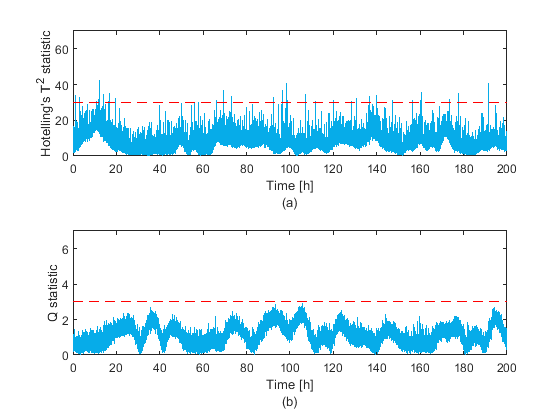

% Create the figure for the fault detection control charts
figure()

% Plot the fault detection Hotelling's T2 statistic
subplot(2,1,1)
plot(fault_detection_time/(60*60), fault_detection_T2, '-', 'Color', blue, 'LineWidth',line_width)
hold on
plot([0 fault_detection_time(end)/(60*60)], [T2_ALPHA T2_ALPHA], '--r', 'LineWidth',line_width)
hold off
ylabel("Hotelling's T^{2} statistic")
xlabel(["Time [h]", "(a)"])
ylim([0, 70])

% Plot the fault detection Q statistic
subplot(2,1,2)
plot(fault_detection_time/(60*60), fault_detection_Q, '-', 'Color', blue, 'LineWidth',line_width)
hold on
plot([0 fault_detection_time(end)/(60*60)], [Q_ALPHA Q_ALPHA], '--r', 'LineWidth',line_width)
hold off
ylabel("Q statistic")
xlabel(["Time [h]", "(b)"])
ylim([0, 7])

% Save the current figure
if (SAVE_IMAGES)
    print('fault_detection/output/fault_detection/fault_detection_control_chart', '-dpng', '-r600')
end